numCarr = 2048;
modOrder = 4;  % for 4-QAM
bitsPerSymbol = log2(modOrder)

bitsPerSymbol = 2

cycPre = 64;

GB_len = numCarr/16;
left_gb = 1:GB_len

left_gb =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


right_gb = (numCarr-GB_len+1):numCarr

right_gb =         1921        1922        1923        1924        1925        1926        1927        1928        1929        1930        1931        1932        1933        1934        1935        1936        1937        1938        1939        1940        1941        1942        1943        1944        1945        1946        1947        1948        1949        1950        1951        1952        1953        1954        1955        1956        1957        1958        1959        1960        1961        1962        1963        1964        1965        1966        1967        1968        1969        1970


if mod(numCarr,2) == 0
    mid_guard = (numCarr/2)+1
else
    mid_guard = (numCarr+1)/2
end

mid_guard = 1025


nullIdx = [left_gb, mid_guard, right_gb]'

nullIdx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10



numDataCarrs = numCarr-length(nullIdx)

numDataCarrs = 1791

My_Pilot_Bits = randi([0,1],numDataCarrs*bitsPerSymbol,1)

My_Pilot_Bits =      0
     1
     0
     0
     0
     0
     1
     1
     1
     0


my_QAM_pilot = qammod(My_Pilot_Bits,modOrder,"InputType","bit","UnitAveragePower",true)

my_QAM_pilot =   -0.7071 - 0.7071i
  -0.7071 + 0.7071i
  -0.7071 + 0.7071i
   0.7071 - 0.7071i
   0.7071 + 0.7071i
  -0.7071 - 0.7071i
  -0.7071 + 0.7071i
  -0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i


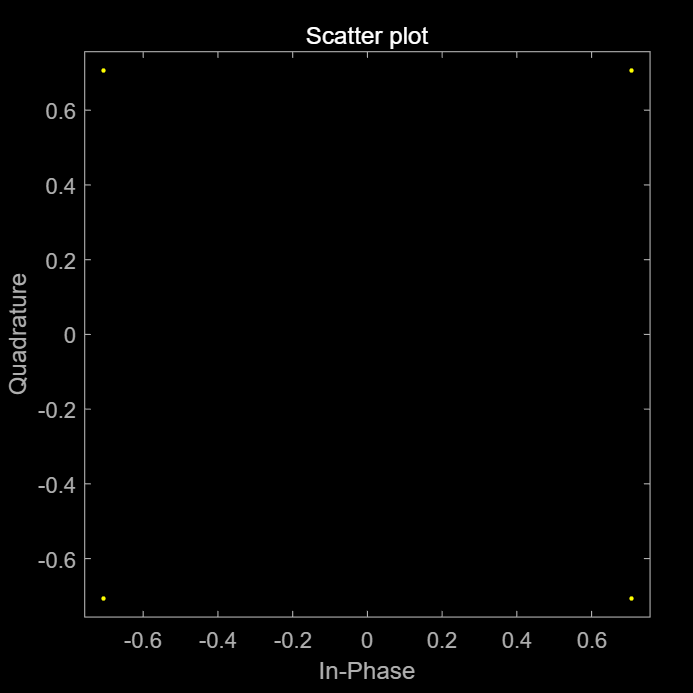


figure()
scatterplot(my_QAM_pilot)

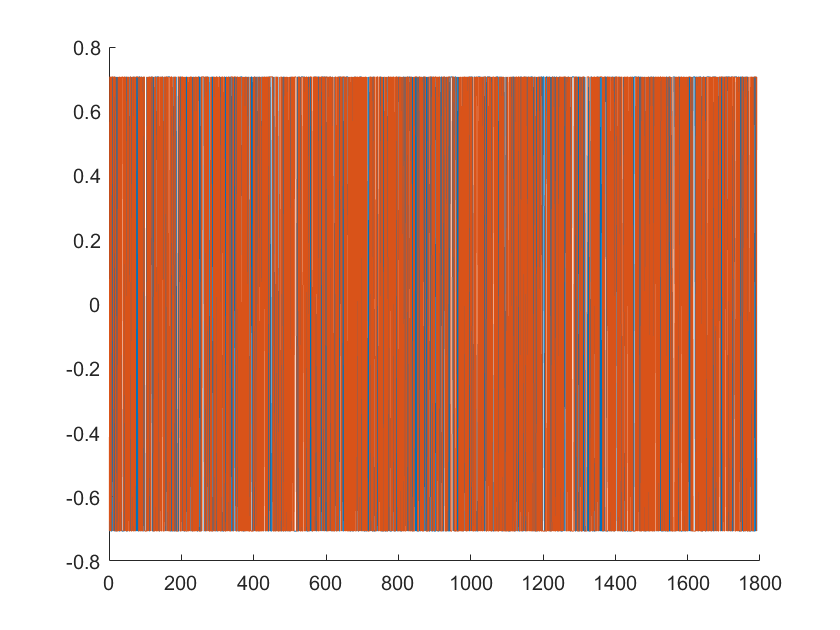


figure()
hold on
plot(real(my_QAM_pilot))
plot(imag(my_QAM_pilot))
hold off


My_Pilot = ofdmmod(my_QAM_pilot,numCarr,cycPre,nullIdx)

My_Pilot =    0.0016 + 0.0110i
  -0.0114 + 0.0111i
   0.0149 + 0.0159i
   0.0065 - 0.0037i
  -0.0246 - 0.0072i
  -0.0030 + 0.0092i
   0.0118 + 0.0165i
   0.0032 - 0.0046i
  -0.0127 - 0.0066i
   0.0037 - 0.0043i


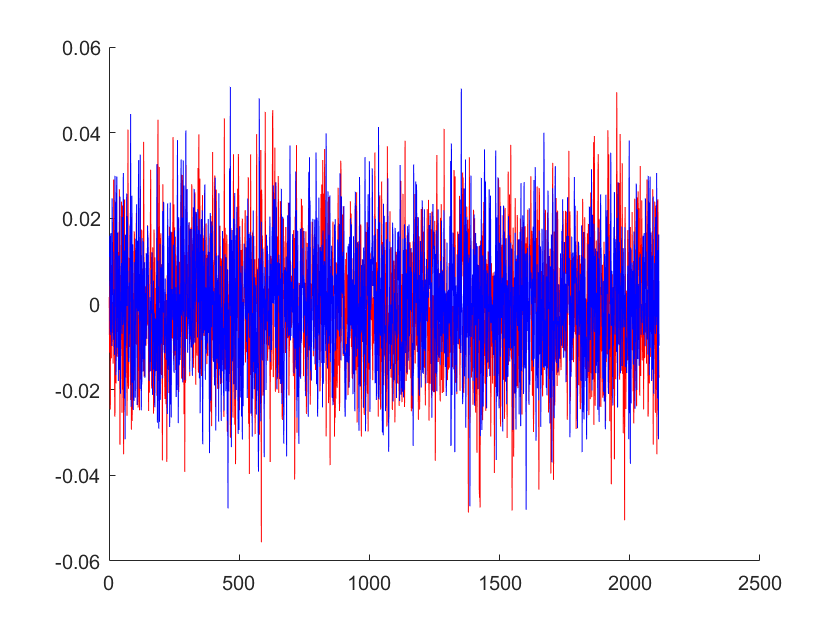


save('D:\Bristol\23-24\Project\Hardware\Simpler\Tx2\4QAM\My_Pilot.mat', 'My_Pilot_Bits','my_QAM_pilot','My_Pilot');

figure()
hold on
plot(real(My_Pilot),'r')
plot(imag(My_Pilot),'b')
hold off


temp = load('D:\Bristol\23-24\Project\Hardware\Simpler\Tx2\4QAM\My_Pilot.mat','My_Pilot_Bits','my_QAM_pilot','My_Pilot')

temp = 包含以下字段的 struct :
    My_Pilot_Bits: [3582×1 double]
     my_QAM_pilot: [1791×1 double]
         My_Pilot: [2112×1 double]


read_pilot = temp.My_Pilot

read_pilot =    0.0016 + 0.0110i
  -0.0114 + 0.0111i
   0.0149 + 0.0159i
   0.0065 - 0.0037i
  -0.0246 - 0.0072i
  -0.0030 + 0.0092i
   0.0118 + 0.0165i
   0.0032 - 0.0046i
  -0.0127 - 0.0066i
   0.0037 - 0.0043i


read_QAM = temp.my_QAM_pilot

read_QAM =   -0.7071 - 0.7071i
  -0.7071 + 0.7071i
  -0.7071 + 0.7071i
   0.7071 - 0.7071i
   0.7071 + 0.7071i
  -0.7071 - 0.7071i
  -0.7071 + 0.7071i
  -0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i


read_bits = temp.My_Pilot_Bits

read_bits =      0
     1
     0
     0
     0
     0
     1
     1
     1
     0
